make sure we understand what's in all these different files



h5disp("/Volumes/Data/laion/laion2B-en-pca32v2-n=100K.h5");

HDF5 laion2B-en-pca32v2-n=100K.h5 
Group '/' 
    Dataset 'pca32' 
        Size:  32x100000
        MaxSize:  32x100000
        Datatype:   H5T_IEEE_F32LE (single)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


data = h5read("/Volumes/Data/laion/laion2B-en-pca32v2-n=100K.h5","/pca32");
data = data';


queries = h5read("/Volumes/Data/laion/public-queries-10k-pca32v2.h5","/pca32");
queries = queries';



gold_s_dists = h5read("/Volumes/Data/laion/laion2B-en-public-gold-standard-v2-100K.h5","/dists");
gold_s_nns = h5read("/Volumes/Data/laion/laion2B-en-public-gold-standard-v2-100K.h5","/knns");
gold_s_dists = gold_s_dists';
gold_s_nns = gold_s_nns';




q1 = euc(queries(1,:),data);
[dists,ord] = sort(q1);


gs_nns = gold_s_nns(1,:);
good = size(intersect(ord(1:100),gs_nns));




data768 = h5read("/Volumes/Data/laion/laion2B-en-clip768v2-n=300K.h5","/emb");
data768 = data768';

check there are zero distances in the original data

small = euc(queries768(56,:),data768(8982,:))

small = single
8.6078e-05

%that's pretty small!!

establish that the published figures are actually 1-dot product and not a proper distance




queries768 = h5read("/Volumes/Data/laion/public-queries-10k-clip768v2.h5","/emb");
queries768 = queries768';


queryNo = 6;
queryRep = queries768(queryNo,:);
gs_nns = gold_s_nns(queryNo,:);

Unrecognized function or variable 'gold_s_nns'.

nn_data = data768(gs_nns,:);



compare the dot product dists with proper metrics for various queries

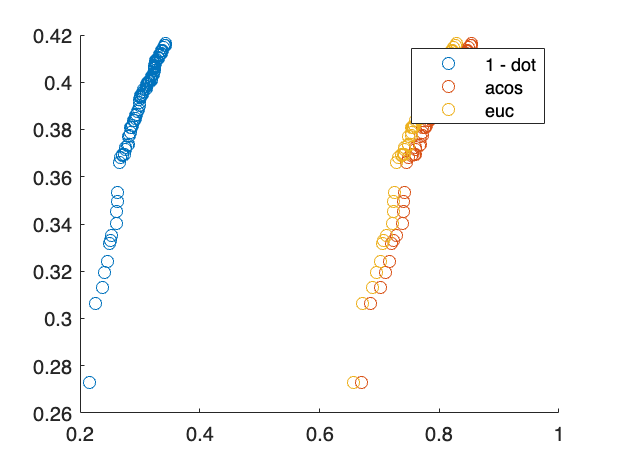



queryNo = 6;
queryRep = queries768(queryNo,:);
gs_nns = gold_s_nns(queryNo,:);

nn_data = data768(gs_nns,:);

% myDists = euc(queries768(1,:),nn1data);

myDists = zeros(3,100);

for i = 1 : 100
    myDists(1,i) = 1 - dot(queryRep,nn_data(i,:));
    myDists(2,i) = acos(dot(queryRep,nn_data(i,:)));
    myDists(3,i) = euc(queryRep,nn_data(i,:));
end

gsDists = gold_s_dists(1,:);
figure;
hold on;
scatter(myDists(1,:),gsDists);
scatter(myDists(2,:),gsDists);
scatter(myDists(3,:),gsDists);
legend("1 - dot","acos","euc");
hold off;